## Q1 - part b | Output Error

clear; clc;

%%

load q1_402123100.mat

u_val = u(length(u)/2+1:end);
v_val = v(length(u)/2+1:end);
z_val = z(length(u)/2+1:end);
y_val = y(length(u)/2+1:end);

u = u(1:length(u)/2);
v = v(1:length(v)/2);
z = z(1:length(z)/2);
y = y(1:length(y)/2);



%%
Ts = 0.1; 
t = 0:Ts:length(u)*Ts-Ts;
N = length(y);

data = iddata(y,u,Ts);
%%



fprintf("===============Degree Extraction | Best Fit Lowest Error Method====================\n")

===============Degree Extraction | Best Fit Lowest Error Method====================


R2s  = [];
MSEs = [];
dets = [];
vars = [];
covs = [];
S_hats = [];
AICs = [];
ps = [];
k = 5;

for degree=1:1:100
    na = degree;
    nb = degree;
    nk = 1;
    p = na+nb+1;

    try
        sys = oe(data,[na nb nk]);
        oe_y_hat = lsim(sys,u_val,t);
    catch
        break;
    end
    
    [r2_oe, mse_oe] = rSQR(y_val, oe_y_hat);

    error = y_val - oe_y_hat;
    S_hat = 0;
    for i=1:length(error)
        S_hat = S_hat + error(i)^2;
    end
    
    AIC = AIC_criteria(S_hat, k, p, N);
    variance = Variance_criteria(S_hat, N, p);

%     covariance = variance*inv(U'*U);
%     detUTU = det(U*U');
%     covs = [covs; covariance];

    fprintf(">>> Degree = %d : R2=%f | MSE=%f | var=%f | s_hat=%f |\n", degree, r2_oe, mse_oe, variance, S_hat)
    fprintf("-------------------------------------------------------------\n")

    ps = [ps; p];
    R2s = [R2s; r2_oe];
    MSEs = [MSEs; mse_oe];
%     dets = [dets; detUTU];
    vars = [vars; variance];
    
    S_hats = [S_hats; S_hat];
    AICs = [AICs; AIC];
end

>>> Degree = 1 : R2=0.258071 | MSE=4.108655 | var=4.133456 | s_hat=2054.327691 |


-------------------------------------------------------------


>>> Degree = 2 : R2=0.774381 | MSE=1.249432 | var=1.262052 | s_hat=624.715848 |


-------------------------------------------------------------


>>> Degree = 3 : R2=0.773828 | MSE=1.252498 | var=1.270282 | s_hat=626.248987 |


-------------------------------------------------------------


>>> Degree = 4 : R2=0.773307 | MSE=1.255380 | var=1.278391 | s_hat=627.690128 |


-------------------------------------------------------------


>>> Degree = 5 : R2=0.773503 | MSE=1.254297 | var=1.282512 | s_hat=627.148454 |


-------------------------------------------------------------


>>> Degree = 6 : R2=0.819775 | MSE=0.998051 | var=1.024693 | s_hat=499.025310 |


-------------------------------------------------------------


>>> Degree = 7 : R2=0.819510 | MSE=0.999520 | var=1.030433 | s_hat=499.760058 |


-------------------------------------------------------------


>>> Degree = 8 : R2=0.819094 | MSE=1.001824 | var=1.037085 | s_hat=500.912096 |


-------------------------------------------------------------


>>> Degree = 9 : R2=0.774039 | MSE=1.251331 | var=1.300759 | s_hat=625.665267 |


-------------------------------------------------------------


>>> Degree = 10 : R2=0.728888 | MSE=1.501366 | var=1.567188 | s_hat=750.682957 |


-------------------------------------------------------------


>>> Degree = 11 : R2=0.809830 | MSE=1.053122 | var=1.103901 | s_hat=526.560848 |


-------------------------------------------------------------


>>> Degree = 12 : R2=0.813455 | MSE=1.033051 | var=1.087422 | s_hat=516.525338 |


-------------------------------------------------------------


>>> Degree = 13 : R2=0.815035 | MSE=1.024300 | var=1.082770 | s_hat=512.150073 |


-------------------------------------------------------------


>>> Degree = 14 : R2=0.815450 | MSE=1.022004 | var=1.084930 | s_hat=511.001997 |


-------------------------------------------------------------


>>> Degree = 15 : R2=0.814503 | MSE=1.027246 | var=1.095145 | s_hat=513.622887 |


-------------------------------------------------------------


>>> Degree = 16 : R2=0.810106 | MSE=1.051596 | var=1.125905 | s_hat=525.797780 |


-------------------------------------------------------------


>>> Degree = 17 : R2=0.814559 | MSE=1.026939 | var=1.104235 | s_hat=513.469343 |


-------------------------------------------------------------


>>> Degree = 18 : R2=0.814718 | MSE=1.026054 | var=1.108050 | s_hat=513.027149 |


-------------------------------------------------------------


>>> Degree = 19 : R2=0.810706 | MSE=1.048272 | var=1.136954 | s_hat=524.135960 |


-------------------------------------------------------------


>>> Degree = 20 : R2=0.813597 | MSE=1.032262 | var=1.124469 | s_hat=516.131153 |


-------------------------------------------------------------


>>> Degree = 21 : R2=0.737888 | MSE=1.451527 | var=1.588104 | s_hat=725.763435 |


-------------------------------------------------------------


>>> Degree = 22 : R2=0.796763 | MSE=1.125487 | var=1.236799 | s_hat=562.743527 |


-------------------------------------------------------------


>>> Degree = 23 : R2=0.799472 | MSE=1.110483 | var=1.225699 | s_hat=555.241581 |


-------------------------------------------------------------


>>> Degree = 24 : R2=0.797271 | MSE=1.122674 | var=1.244649 | s_hat=561.336761 |


-------------------------------------------------------------


>>> Degree = 25 : R2=0.793943 | MSE=1.141104 | var=1.270717 | s_hat=570.551863 |


-------------------------------------------------------------


>>> Degree = 26 : R2=0.787355 | MSE=1.177586 | var=1.317210 | s_hat=588.793082 |


-------------------------------------------------------------


>>> Degree = 27 : R2=0.796150 | MSE=1.128881 | var=1.268405 | s_hat=564.440426 |


-------------------------------------------------------------


>>> Degree = 28 : R2=0.361116 | MSE=3.538012 | var=3.993241 | s_hat=1769.005957 |


-------------------------------------------------------------


>>> Degree = 29 : R2=0.767369 | MSE=1.288263 | var=1.460616 | s_hat=644.131488 |


-------------------------------------------------------------


>>> Degree = 30 : R2=0.775192 | MSE=1.244943 | var=1.417931 | s_hat=622.471595 |


-------------------------------------------------------------


>>> Degree = 31 : R2=0.773751 | MSE=1.252922 | var=1.433549 | s_hat=626.460978 |


-------------------------------------------------------------


>>> Degree = 32 : R2=0.749858 | MSE=1.385237 | var=1.592227 | s_hat=692.618625 |


-------------------------------------------------------------


>>> Degree = 33 : R2=0.792220 | MSE=1.150642 | var=1.328686 | s_hat=575.321124 |


-------------------------------------------------------------


>>> Degree = 34 : R2=0.774274 | MSE=1.250027 | var=1.450148 | s_hat=625.013640 |


-------------------------------------------------------------


>>> Degree = 35 : R2=0.685256 | MSE=1.742992 | var=2.031459 | s_hat=871.496068 |


-------------------------------------------------------------


>>> Degree = 36 : R2=0.747975 | MSE=1.395663 | var=1.634266 | s_hat=697.831722 |


-------------------------------------------------------------


>>> Degree = 37 : R2=0.779104 | MSE=1.223279 | var=1.439152 | s_hat=611.639642 |


-------------------------------------------------------------


>>> Degree = 38 : R2=0.779498 | MSE=1.221098 | var=1.443378 | s_hat=610.548956 |


-------------------------------------------------------------


>>> Degree = 39 : R2=-0.009231 | MSE=5.588923 | var=6.637676 | s_hat=2794.461730 |


-------------------------------------------------------------


>>> Degree = 40 : R2=-1.523583 | MSE=13.975108 | var=16.676740 | s_hat=6987.553970 |


-------------------------------------------------------------


>>> Degree = 41 : R2=-0.307603 | MSE=7.241251 | var=8.682555 | s_hat=3620.625315 |


-------------------------------------------------------------


>>> Degree = 42 : R2=0.551223 | MSE=2.485240 | var=2.994265 | s_hat=1242.619798 |


-------------------------------------------------------------


>>> Degree = 43 : R2=0.762137 | MSE=1.317237 | var=1.594718 | s_hat=658.618460 |


-------------------------------------------------------------


>>> Degree = 44 : R2=0.737532 | MSE=1.453494 | var=1.768241 | s_hat=726.747124 |


-------------------------------------------------------------


>>> Degree = 45 : R2=0.611457 | MSE=2.151673 | var=2.630407 | s_hat=1075.836445 |


-------------------------------------------------------------


>>> Degree = 46 : R2=0.651850 | MSE=1.927985 | var=2.368532 | s_hat=963.992606 |


-------------------------------------------------------------


>>> Degree = 47 : R2=0.782312 | MSE=1.205515 | var=1.488291 | s_hat=602.757734 |


-------------------------------------------------------------


>>> Degree = 48 : R2=0.752382 | MSE=1.371261 | var=1.701317 | s_hat=685.630609 |


-------------------------------------------------------------


>>> Degree = 49 : R2=0.248283 | MSE=4.162859 | var=5.190597 | s_hat=2081.429510 |


-------------------------------------------------------------


>>> Degree = 50 : R2=0.742692 | MSE=1.424923 | var=1.785618 | s_hat=712.461505 |


-------------------------------------------------------------


>>> Degree = 51 : R2=0.763749 | MSE=1.308311 | var=1.647746 | s_hat=654.155302 |


-------------------------------------------------------------


>>> Degree = 52 : R2=0.742317 | MSE=1.427000 | var=1.806329 | s_hat=713.499951 |


-------------------------------------------------------------


>>> Degree = 53 : R2=0.596762 | MSE=2.233055 | var=2.841037 | s_hat=1116.527718 |


-------------------------------------------------------------


>>> Degree = 54 : R2=0.744846 | MSE=1.412995 | var=1.806899 | s_hat=706.497495 |


-------------------------------------------------------------


>>> Degree = 55 : R2=0.138754 | MSE=4.769413 | var=6.130352 | s_hat=2384.706742 |


-------------------------------------------------------------


>>> Degree = 56 : R2=0.732106 | MSE=1.483547 | var=1.916727 | s_hat=741.773441 |


-------------------------------------------------------------


>>> Degree = 57 : R2=0.710902 | MSE=1.600968 | var=2.079179 | s_hat=800.484029 |


-------------------------------------------------------------


>>> Degree = 58 : R2=0.150552 | MSE=4.704076 | var=6.141091 | s_hat=2352.038018 |


-------------------------------------------------------------


>>> Degree = 59 : R2=-1.220707 | MSE=12.297839 | var=16.138897 | s_hat=6148.919649 |


-------------------------------------------------------------


>>> Degree = 60 : R2=0.759676 | MSE=1.330869 | var=1.755764 | s_hat=665.434660 |


-------------------------------------------------------------


>>> Degree = 61 : R2=0.466294 | MSE=2.955560 | var=3.919840 | s_hat=1477.779856 |


-------------------------------------------------------------


>>> Degree = 62 : R2=0.742067 | MSE=1.428380 | var=1.904507 | s_hat=714.190245 |


-------------------------------------------------------------


>>> Degree = 63 : R2=0.690543 | MSE=1.713711 | var=2.297200 | s_hat=856.855426 |


-------------------------------------------------------------


>>> Degree = 64 : R2=-5.513148 | MSE=36.068542 | var=48.609894 | s_hat=18034.270754 |


-------------------------------------------------------------


fprintf("=================================================================\n")


%%

fprintf("===============Degree Extraction | BestFit Method=================\n")

===============Degree Extraction | BestFit Method=================



bestFitDegree = find(S_hats == min(S_hats));

fprintf(">>> Looking for the minimum SSE , leads to: \n")

>>> Looking for the minimum SSE , leads to: 


fprintf("    Degree = %d \n", bestFitDegree)

    Degree = 6 


na = bestFitDegree;
nb = bestFitDegree;

p = na+nb+1;

BestFitModel = oe(data, [na nb 1])

BestFitModel =
Discrete-time OE model: y(t) = [B(z)/F(z)]u(t) + e(t)                                        
  B(z) = -0.02 z^-1 + 0.06048 z^-2 + 0.04228 z^-3 - 0.04339 z^-4 - 0.09412 z^-5 + 0.1075 z^-6
                                                                                             
  F(z) = 1 - 1.13 z^-1 - 0.7627 z^-2 + 0.3486 z^-3 + 0.8758 z^-4 - 0.00416 z^-5 - 0.3221 z^-6
                                                                                             
Sample time: 0.1 seconds
  
Parameterization:
   Polynomial orders:   nb=6   nf=6   nk=1
   Number of free coefficients: 12
   Use "polydata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                       
Estimated using OE on time domain data "data".
Fit to estimation data: 52.54%                
FPE: 0.993, MSE: 0.9464                       


BestFit_y_hat = lsim(BestFitModel, u_val, t);
[oe_BestFit_r2, oe_BestFit_mse] = rSQR(y_val, BestFit_y_hat);



%%

fprintf("===============Degree Extraction | Variance Method====================\n")

===============Degree Extraction | Variance Method====================




minVarIndex = find(vars == min(vars));
fprintf(">>> Since the minimum variance value occurs in iteration %d ;\n", minVarIndex)

>>> Since the minimum variance value occurs in iteration 6 ;


fprintf("    Degree = %d \n", minVarIndex)

    Degree = 6 


na = minVarIndex;
nb = minVarIndex;
p = na+nb;

VarModel = oe(data, [na nb 1])

VarModel =
Discrete-time OE model: y(t) = [B(z)/F(z)]u(t) + e(t)                                        
  B(z) = -0.02 z^-1 + 0.06048 z^-2 + 0.04228 z^-3 - 0.04339 z^-4 - 0.09412 z^-5 + 0.1075 z^-6
                                                                                             
  F(z) = 1 - 1.13 z^-1 - 0.7627 z^-2 + 0.3486 z^-3 + 0.8758 z^-4 - 0.00416 z^-5 - 0.3221 z^-6
                                                                                             
Sample time: 0.1 seconds
  
Parameterization:
   Polynomial orders:   nb=6   nf=6   nk=1
   Number of free coefficients: 12
   Use "polydata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                       
Estimated using OE on time domain data "data".
Fit to estimation data: 52.54%                
FPE: 0.993, MSE: 0.9464                       


Var_y_hat = lsim(VarModel, u_val, t);

fprintf("=================================================================\n")


%%

fprintf("===============Degree Extraction | AIC Method====================\n")

===============Degree Extraction | AIC Method====================



minAICIndex = find(AICs == min(AICs));
fprintf(">>> Since the minimum AIC value (k=%.2f) occurs in iteration %d ;\n", k, minAICIndex)

>>> Since the minimum AIC value (k=5.00) occurs in iteration 6 ;


fprintf("    Degree = %d \n", minAICIndex)

    Degree = 6 



na = minAICIndex;
nb = minAICIndex;
p = na+nb+1;

AICModel =  oe(data, [na nb 1])

AICModel =
Discrete-time OE model: y(t) = [B(z)/F(z)]u(t) + e(t)                                        
  B(z) = -0.02 z^-1 + 0.06048 z^-2 + 0.04228 z^-3 - 0.04339 z^-4 - 0.09412 z^-5 + 0.1075 z^-6
                                                                                             
  F(z) = 1 - 1.13 z^-1 - 0.7627 z^-2 + 0.3486 z^-3 + 0.8758 z^-4 - 0.00416 z^-5 - 0.3221 z^-6
                                                                                             
Sample time: 0.1 seconds
  
Parameterization:
   Polynomial orders:   nb=6   nf=6   nk=1
   Number of free coefficients: 12
   Use "polydata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                       
Estimated using OE on time domain data "data".
Fit to estimation data: 52.54%                
FPE: 0.993, MSE: 0.9464                       


AIC_y_hat = lsim(AICModel, u_val, t);

fprintf("=================================================================\n")


%%

fprintf("===============Degree Extraction | F test Method====================\n")

===============Degree Extraction | F test Method====================


winScore = 0;
winner = 1;
for i=2:length(ps)
    first = winner;
    second = i;
    winScore = finv(0.95, ps(second)-ps(first), N-ps(first));
    score = ((S_hats(first)-S_hats(second))/(ps(second)-ps(first)))/((S_hats(first))/(N-ps(first)));
    if score > winScore
        winner = i;
    end
end
fprintf(">>> The F test is suggesting the best model with the m=%.2f as\n", winScore)

>>> The F test is suggesting the best model with the m=1.26 as


fprintf("    Degree = %d \n", winner)

    Degree = 6 



na = winner;
nb = winner;
p = na+nb+1;

FTestModel =  oe(data, [na nb 1])

FTestModel =
Discrete-time OE model: y(t) = [B(z)/F(z)]u(t) + e(t)                                        
  B(z) = -0.02 z^-1 + 0.06048 z^-2 + 0.04228 z^-3 - 0.04339 z^-4 - 0.09412 z^-5 + 0.1075 z^-6
                                                                                             
  F(z) = 1 - 1.13 z^-1 - 0.7627 z^-2 + 0.3486 z^-3 + 0.8758 z^-4 - 0.00416 z^-5 - 0.3221 z^-6
                                                                                             
Sample time: 0.1 seconds
  
Parameterization:
   Polynomial orders:   nb=6   nf=6   nk=1
   Number of free coefficients: 12
   Use "polydata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                       
Estimated using OE on time domain data "data".
Fit to estimation data: 52.54%                
FPE: 0.993, MSE: 0.9464                       


FTest_y_hat = lsim(FTestModel, u_val, t);

fprintf("=================================================================\n")


%%

[BestFit_r2, BestFit_mse] = rSQR(y_val, BestFit_y_hat);
[Var_r2, Var_mse] = rSQR(y_val, Var_y_hat);
[AIC_r2, AIC_mse] = rSQR(y_val, AIC_y_hat);
[FTest_r2, FTest_mse] = rSQR(y_val, FTest_y_hat);

fprintf("===================Evaluation | R2 Metric======================\n")

===================Evaluation | R2 Metric======================


fprintf("---------------------------------------------------------------\n")

---------------------------------------------------------------


fprintf(">>> BestFit Lowest Error Method:\n")

>>> BestFit Lowest Error Method:


fprintf("    R2 value : %.4f   | MSE : %.4f \n", BestFit_r2, BestFit_mse)

    R2 value : 0.8198   | MSE : 0.9981 


fprintf("---------------------------------------------------------------\n")

---------------------------------------------------------------


fprintf(">>> Variance Method:\n")

>>> Variance Method:


fprintf("    R2 value : %.4f   | MSE : %.4f \n", Var_r2, Var_mse)

    R2 value : 0.8198   | MSE : 0.9981 


fprintf("---------------------------------------------------------------\n")

---------------------------------------------------------------


fprintf(">>> AIC Method:\n")

>>> AIC Method:


fprintf("    R2 value : %.4f   | MSE : %.4f \n", AIC_r2, AIC_mse)

    R2 value : 0.8198   | MSE : 0.9981 


fprintf("---------------------------------------------------------------\n")

---------------------------------------------------------------


fprintf(">>> FTest Method:\n")

>>> FTest Method:


fprintf("    R2 value : %.4f   | MSE : %.4f \n", FTest_r2, FTest_mse)

    R2 value : 0.8198   | MSE : 0.9981 


fprintf("---------------------------------------------------------------\n")

---------------------------------------------------------------


% fprintf(">>> Winner:\n")
% fprintf("    The best R2 value is \n")
fprintf("===============================================================\n")


%%

BestFitError = y_val - BestFit_y_hat;
VarError = y_val - Var_y_hat;
AICError = y_val - AIC_y_hat;
FTestError = y_val - FTest_y_hat;

for k=0:N-1
    BestFit_Ree(k+1,1) = AutoCorrelate(BestFitError, k);
    Var_Ree(k+1,1) = AutoCorrelate(VarError, k);
    AIC_Ree(k+1,1) = AutoCorrelate(AICError, k);
    FTest_Ree(k+1,1) = AutoCorrelate(FTestError, k);
end

for k=0:N-1
    BestFit_Rue(k+1,1) = CrossCorrelate(u_val, BestFitError, k);
    Var_Rue(k+1,1) = CrossCorrelate(u_val, VarError, k);
    AIC_Rue(k+1,1) = CrossCorrelate(u_val, AICError, k);
    FTest_Rue(k+1,1) = CrossCorrelate(u_val, FTestError, k);
end


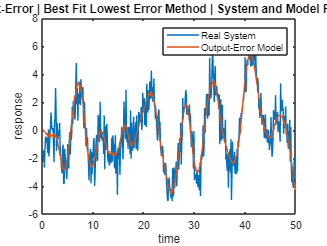


%%
figure(1)
plot(t,y_val,t,BestFit_y_hat)
legend('Real System','Output-Error Model')
title(" Output-Error | Best Fit Lowest Error Method | System and Model Response")
xlabel("time")
ylabel("response")

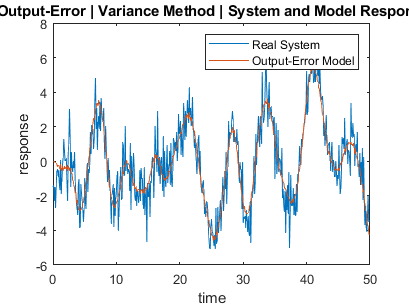


figure(2)
plot(t,y_val,t,Var_y_hat)
legend('Real System','Output-Error Model')
title(" Output-Error | Variance Method | System and Model Response")
xlabel("time")
ylabel("response")

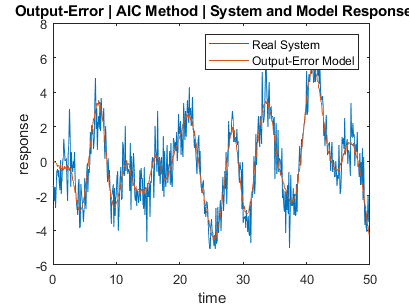


figure(3)
plot(t,y_val,t,AIC_y_hat)
legend('Real System','Output-Error Model')
title(" Output-Error | AIC Method | System and Model Response")
xlabel("time")
ylabel("response")

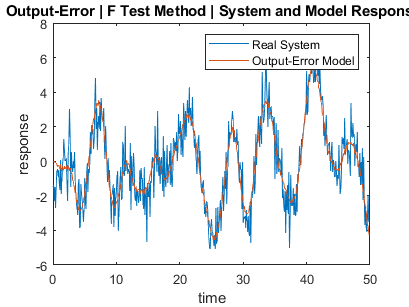


figure(4)
plot(t,y_val,t,FTest_y_hat)
legend('Real System','Output-Error Model')
title(" Output-Error | F Test Method | System and Model Response")
xlabel("time")
ylabel("response")

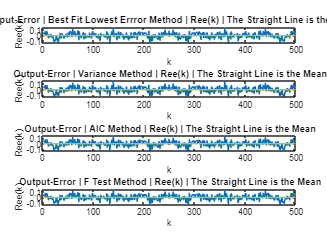


%%

figure(5)
subplot(4,1,1)
plot(1:N-1,BestFit_Ree(2:end), 1:N-1, mean(BestFit_Ree(2:end))*ones(length(1:N-1)))
title(" Output-Error | Best Fit Lowest Errror Method | Ree(k) | The Straight Line is the Mean")
xlabel("k")
ylabel("Ree(k)")

subplot(4,1,2)
plot(1:N-1,Var_Ree(2:end), 1:N-1, mean(Var_Ree(2:end))*ones(length(1:N-1)))
title(" Output-Error | Variance Method | Ree(k) | The Straight Line is the Mean")
xlabel("k")
ylabel("Ree(k)")

subplot(4,1,3)
plot(1:N-1,AIC_Ree(2:end), 1:N-1, mean(AIC_Ree(2:end))*ones(length(1:N-1)))
title(" Output-Error | AIC Method | Ree(k) | The Straight Line is the Mean")
xlabel("k")
ylabel("Ree(k)")

subplot(4,1,4)
plot(1:N-1,FTest_Ree(2:end), 1:N-1, mean(FTest_Ree(2:end))*ones(length(1:N-1)))
title(" Output-Error | F Test Method | Ree(k) | The Straight Line is the Mean")
xlabel("k")
ylabel("Ree(k)")

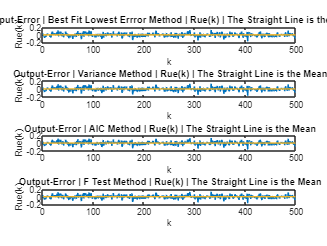


%%

figure(6)
subplot(4,1,1)
plot(1:N-1,BestFit_Rue(2:end), 1:N-1, mean(BestFit_Rue(2:end))*ones(length(1:N-1)))
title(" Output-Error | Best Fit Lowest Errror Method | Rue(k) | The Straight Line is the Mean")
xlabel("k")
ylabel("Rue(k)")

subplot(4,1,2)
plot(1:N-1,Var_Rue(2:end), 1:N-1, mean(Var_Rue(2:end))*ones(length(1:N-1)))
title(" Output-Error | Variance Method | Rue(k) | The Straight Line is the Mean")
xlabel("k")
ylabel("Rue(k)")

subplot(4,1,3)
plot(1:N-1,AIC_Rue(2:end), 1:N-1, mean(AIC_Rue(2:end))*ones(length(1:N-1)))
title(" Output-Error | AIC Method | Rue(k) | The Straight Line is the Mean")
xlabel("k")
ylabel("Rue(k)")

subplot(4,1,4)
plot(1:N-1,FTest_Rue(2:end), 1:N-1, mean(FTest_Rue(2:end))*ones(length(1:N-1)))
title(" Output-Error | F Test Method | Rue(k) | The Straight Line is the Mean")
xlabel("k")
ylabel("Rue(k)")



%%
